**Problem 3 (1)**

Condition: n < p

n = 10; % number of samples
p = 10000; % number of features

% Generate random data for matrix X (centered)
A = randn(n, p);

M = A'*A;
disp("Size of the square matrix:");

Size of the square matrix:


disp(size(M));

       10000       10000



disp("Rank of the square matrix");

Rank of the square matrix


disp(rank(M));

    10



Condition n > p:

n = 1000; % number of samples
p = 100; % number of features

% Generate random data for matrix X (centered)
A = randn(n, p);

M = A'*A;
disp("Size of the square matrix:");

Size of the square matrix:


disp(size(M));

   100   100



disp("Rank of the square matrix");

Rank of the square matrix


disp(rank(M));

   100



As the rank of the matrix < size of the matrix, p > n condition leads to a non invertible matrix. So, the closed form solution fails.

**Problem 3 (2)**

% Given A, y, lr and initial weights
A = [1 2 4; 1 3 5; 1 7 7; 1 8 9];
y = [1; 2; 3; 4];

% Finding the maximum singular value of A
max_singular_value = max(svd(A'*A));

% Learning rate is fixed as 1/max singular value
lr = 1/max_singular_value;
weights = [0; 0; 0];

% Iinitializing a loss row vector to track progress
loss = [];

% Implementing Vanilla Gradient Descent (32k epochs)
for i = 1:32000
    grad = A'*(A*weights - y);
    weights = weights - grad*lr;
    loss(i) = (A*weights - y)' * (A*weights - y);
end

convergence_factor = loss(2:end) ./ loss(1:end-1);
display(convergence_factor);

convergence_factor =     0.9977    0.9977    0.9977    0.9978    0.9978    0.9978    0.9979    0.9979    0.9979    0.9980    0.9980    0.9980    0.9981    0.9981    0.9981    0.9982    0.9982    0.9982    0.9982    0.9983    0.9983    0.9983    0.9984    0.9984    0.9984    0.9984    0.9985    0.9985    0.9985    0.9985    0.9985    0.9986    0.9986    0.9986    0.9986    0.9987    0.9987    0.9987    0.9987    0.9987    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9989    0.9989    0.9989    0.9989


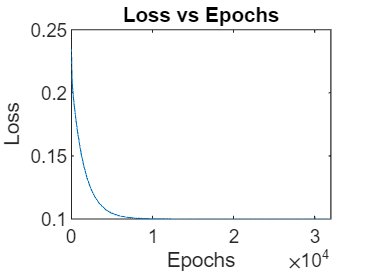


% Plotting the Loss obtained with time
plot(loss);
title("Loss vs Epochs");
xlabel("Epochs");
ylabel("Loss");

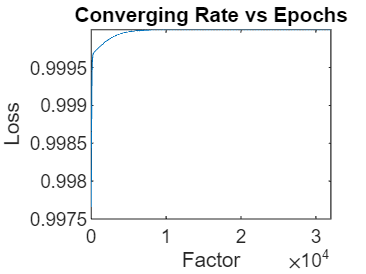


% Plotting the convergence factor for each epoch
plot(convergence_factor);
title("Converging Rate vs Epochs");
xlabel("Factor");
ylabel("Loss");


%Verifying the results obtained from closed form solution
weights2 = pinv(A'*A)*A'*y;

display(weights2);

weights2 =    -1.0000
    0.0333
    0.5333


display(weights);

weights =    -1.0000
    0.0333
    0.5333


From the above weight matrices, we can deduce that Gradient Descent method obtains the optimal solution with almost a Linear Convergence rate with the given learning rate.

**Problem 3 (3)**

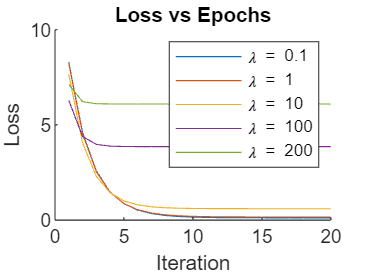

% Define the matrix A and vector y
A = [1, 2, 4; 1, 3, 5; 1, 7, 7; 1, 8, 9];
y = [1; 2; 3; 4];

% Define a range of λ values
lambda_values = [0.1, 1, 10, 100, 200];



% Define the number of iterations
num_iterations = 20;

% Initialize variables to store losses
losses = zeros(length(lambda_values), num_iterations);


% Perform gradient descent for each λ
for k = 1:length(lambda_values)
    lambda = lambda_values(k);
    alpha = 1 / (max(max(A' * A)) + lambda_values(k));

    % Initialize θ0 to [0; 0; 0]
    theta = [0; 0; 0];
    for iteration = 1:num_iterations
        % Compute the gradient for ridge regression
        gradient = -A' * (y - A * theta) + lambda * theta;
        
        % Update θ using the gradient and learning rate
        theta = theta - alpha * gradient;
        
        % Calculate the cost (ridge regression loss)
        loss = (1 / (2 )) * norm(A * theta - y)^2 + (theta' * theta) * (lambda / 2);

        % Store the loss
        losses(k, iteration) = loss;
    end
end

% Plot the loss curves for different λ values
figure;
hold on;
for k = 1:length(lambda_values)
%     plot(1:num_iterations, losses(k, :), 'DisplayName', ['λ = ', num2str(lambda_values(k))]);
    semilogy(1:num_iterations, losses(k, :), 'DisplayName', ['\lambda = ', num2str(lambda_values(k))]);
end

hold off;
xlabel('Iteration');
ylabel('Loss');
title("Loss vs Epochs");
legend;


%Verifying the results obtained from closed form solution
weights2 = pinv(A'*A + lambda_values(5)*eye(size(A, 2)))*A'*y;

To verify, let us compare weights2 and theta

display(weights2);

weights2 =     0.0195
    0.1231
    0.1423


display(theta);

theta =     0.0195
    0.1231
    0.1423
